rng(0);
clear;

Consider the dataset provided within the folder “data_fruit” For this question, you cannot use the functions mean(), cov(), and pca() in Matlab. Each datum is an image of size 80 × 80 pixels with 3 color channels red (R), green (G), and blue (B), i.e., a 80 × 80 × 3 array. For PCA, each image should be resized to a vector of length 19200. For visualization, reshape each vector back to a RGB image of size 80 × 80 pixels using the function reshape(), followed by a shift and rescaling of the values into the range [0, 1], followed by displaying the matrix using the function image(). 

Imgs = readall(imageDatastore('../data/data_fruit/*.png'));  %store image data
[imgsz,~] = size(Imgs);
imgs = zeros(80*80*3,imgsz);
for i = 1:imgsz
    imgs(:,i) = double(reshape(Imgs{i},19200,1))/255;   %reshaping image vectors
end

• (9 points: 1 + 4 + 4) Similar to the analysis done in previous question, find the mean µ, the covariance matrix C, and the top 4 principle eigenvectors of C. Display the mean and the eigenvectors as images (side by side, in the same figure); you can use the function subplot(). Find the top 10 eigenvalues, sort them, and plot their values on a graph. Use the function eigs() for efficient computation. 

mu = sum(imgs,2)/imgsz %mean image

mu =     0.5027
    0.5100
    0.5162
    0.5069
    0.5130
    0.5238
    0.5211
    0.5203
    0.5262
    0.5360


shiftimg = imgs - mu;   %difference of the images from the mean image
C = shiftimg*shiftimg'/imgsz % covariance of the image data

C =     0.1191    0.1171    0.1167    0.1172    0.1169    0.1148    0.1116    0.1099    0.1099    0.1070    0.0995    0.0962    0.0992    0.1018    0.0991    0.0884    0.0765    0.0667    0.0573    0.0489    0.0348    0.0278    0.0259    0.0203    0.0132    0.0073   -0.0006   -0.0105   -0.0204   -0.0276   -0.0299   -0.0294   -0.0291   -0.0296   -0.0322   -0.0337   -0.0337   -0.0355   -0.0337   -0.0365   -0.0340   -0.0300   -0.0313   -0.0312   -0.0281   -0.0241   -0.0158   -0.0129   -0.0100   -0.0067
    0.1171    0.1155    0.1152    0.1153    0.1151    0.1130    0.1095    0.1078    0.1080    0.1051    0.0977    0.0944    0.0974    0.1002    0.0973    0.0869    0.0752    0.0658    0.0565    0.0480    0.0344    0.0272    0.0254    0.0194    0.0121    0.0064   -0.0015   -0.0109   -0.0202   -0.0270   -0.0291   -0.0286   -0.0283   -0.0286   -0.0312   -0.0328   -0.0330   -0.0347   -0.0328   -0.0357   -0.0330   -0.0290   -0.0302   -0.0302   -0.0271   -0.0230   -0.0145   -0.0115   -0.0086   -0

[Q, D] = eigs(C, 10); % eigs(C, k) gets the k largest eigenvals and corresponding eigenvectors
D = diag(D);    %top 10 eigenvals
D(1:4)   %top 4 eigenvalues

ans =   201.5754
  187.3928
  134.6039
   87.4595



Q = Q(:, 1:4)   %only first 4 eigenvectors

Q =     0.0154    0.0005   -0.0057    0.0056
    0.0152    0.0012   -0.0051    0.0060
    0.0151    0.0012   -0.0046    0.0063
    0.0156    0.0002   -0.0053    0.0052
    0.0159    0.0007   -0.0056    0.0050
    0.0159    0.0010   -0.0065    0.0053
    0.0155    0.0006   -0.0079    0.0050
    0.0154    0.0005   -0.0082    0.0049
    0.0159    0.0006   -0.0081    0.0052
    0.0148   -0.0000   -0.0080    0.0055


figure,
tiledlayout(2, 3)
nexttile
imagesc(reshape(mu, 80, 80, 3))'   %mean image

ans =   Image with properties:

           CData: [80×80×3 double]
    CDataMapping: 'scaled'

  Show all properties


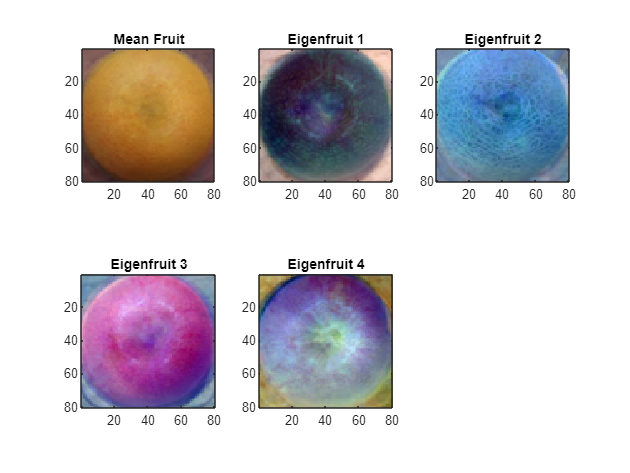

title("Mean Fruit");
pbaspect([1,1,1])
for i = 1:4
    nexttile
    imagesc(reshape(rescale(Q(:, i)), 80, 80, 3));  %eigen fruit images
    pbaspect([1,1,1]);
    title("Eigenfruit "+i);
end

hold off

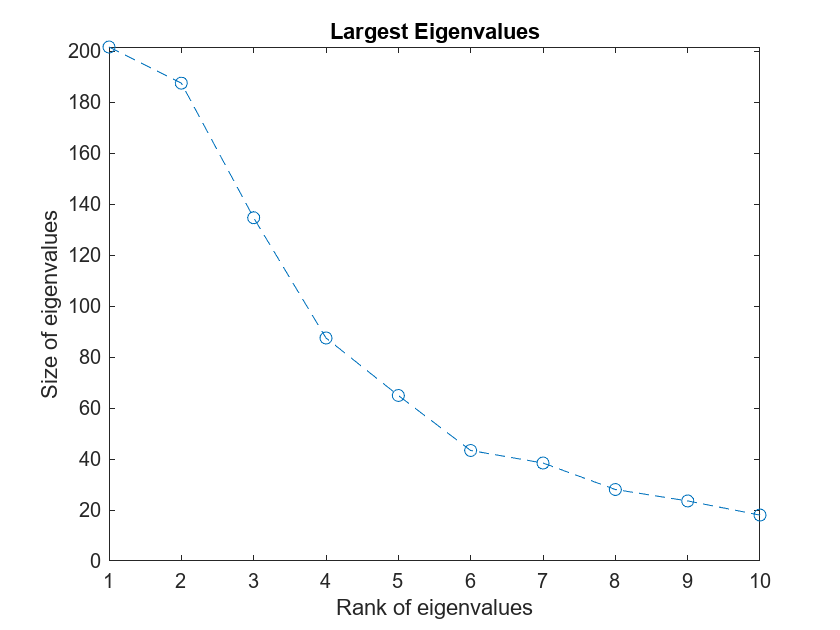


figure
plot(1:10, D,'o--');  %plot of the 10 largest eigenvalues
xlabel('Rank of eigenvalues');
ylabel('Size of eigenvalues')
title("Largest Eigenvalues");

• (8 points: 4 + 4) For each fruit image in the dataset, finds its closest representation as a linear combination of the top 4 eigenvectors added to the mean. Use the measure of closeness as the Frobenius norm of the difference. Describe the algorithm used to produce this closest representation in mathematical terms and describe the logic behind your algorithm. Display the original fruit image and its closest representation, as images (side by side, in the same figure). 

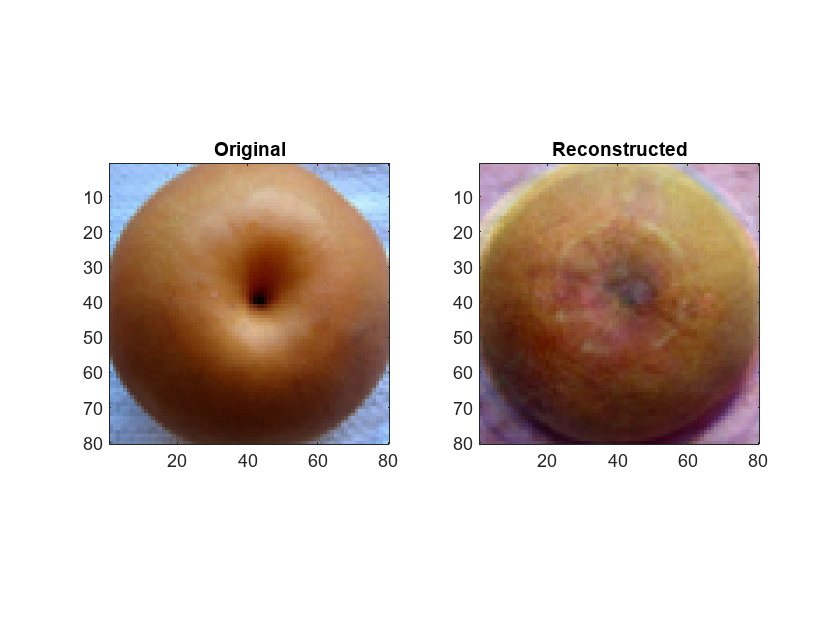

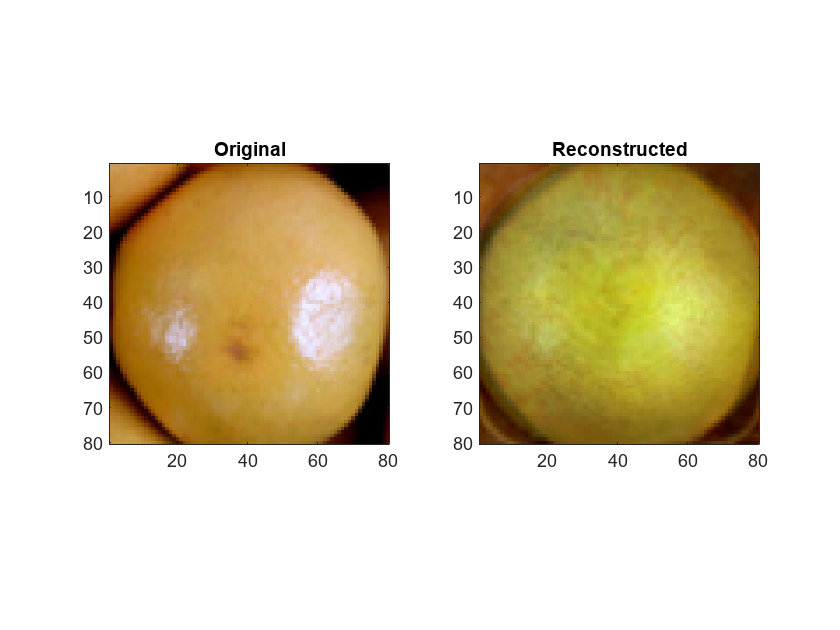

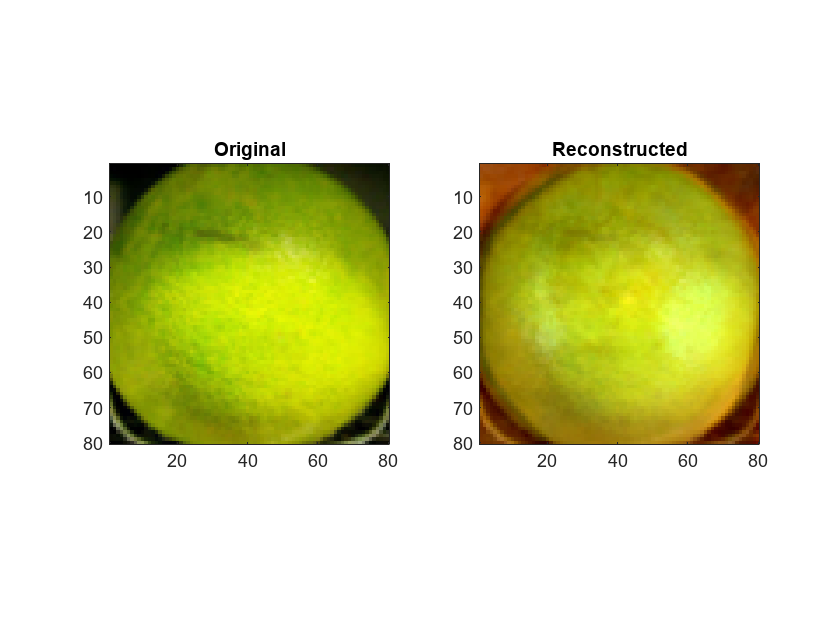

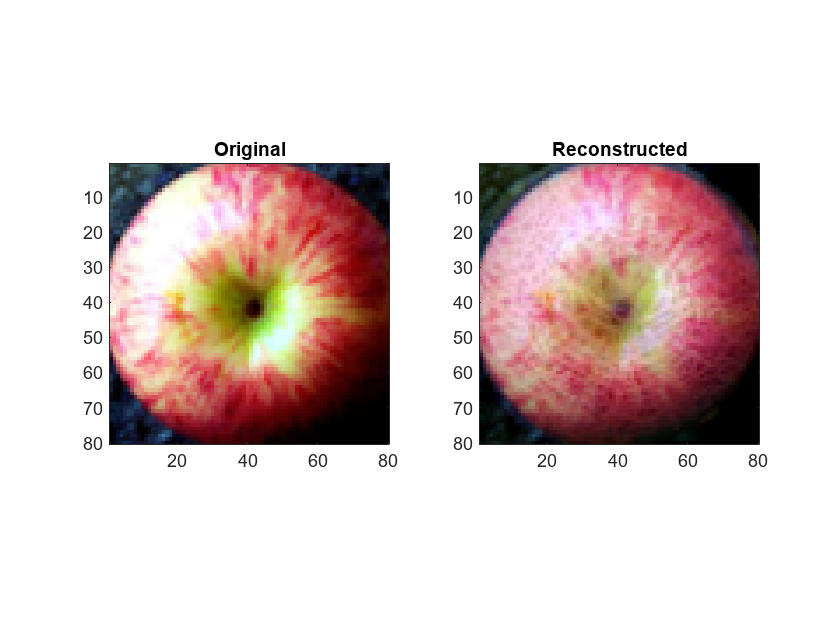

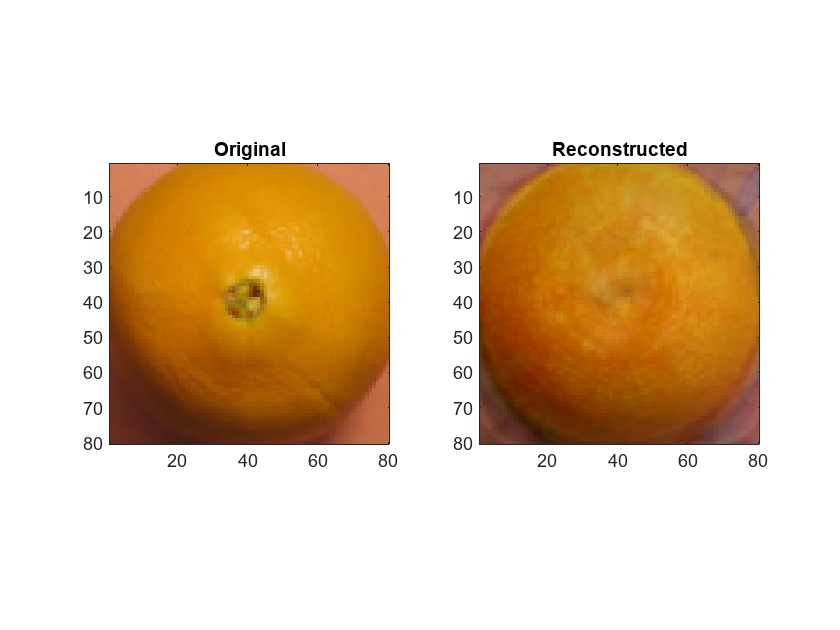

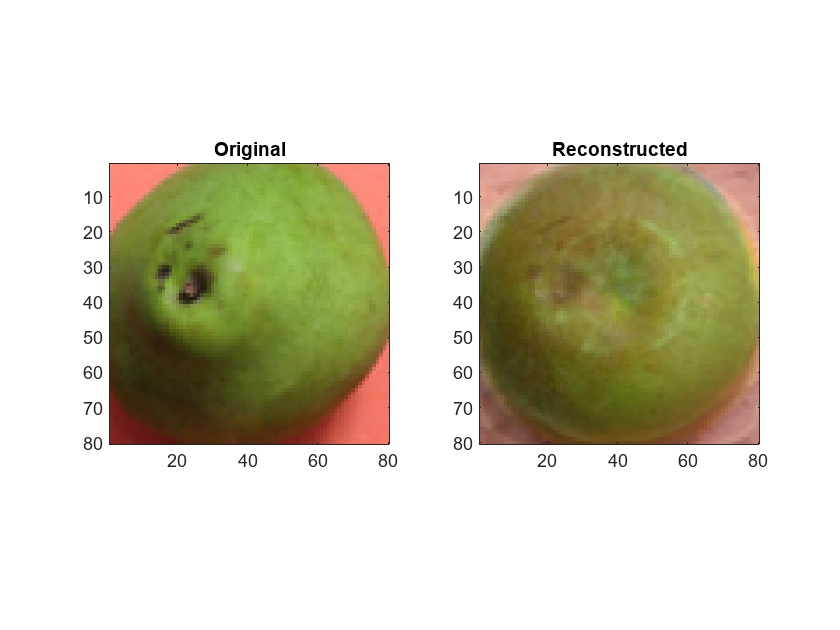

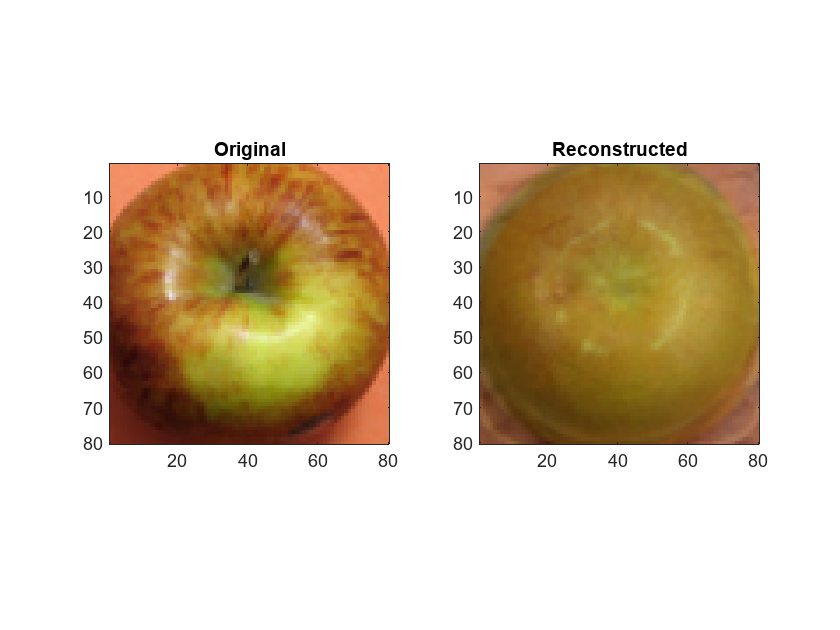

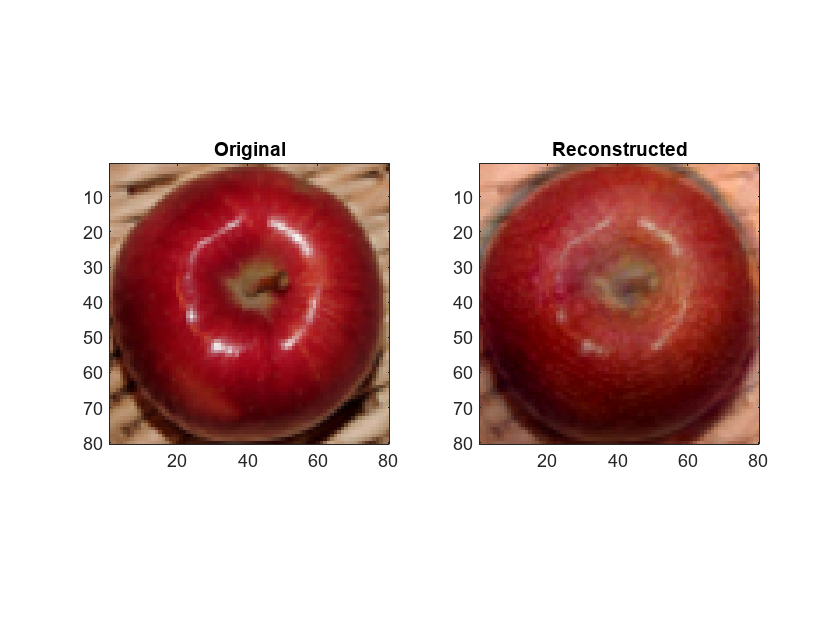

close_rep_mat = mu + Q*Q'*shiftimg;  %closest representation using the top 4 eigenvectors
                            % reconstruct the image by finding the components of the
                            % fruit images along the eigenvectors
for i = 1:imgsz
    pause(0.01)
    figure,
    subplot(1,2,1);
    imagesc(reshape(imgs(:,i), 80, 80, 3)); % original fruit image
    title("Original");
    pbaspect([1,1,1]);

    subplot(1,2,2);
    imagesc(reshape(close_rep_mat(:,i), 80, 80, 3));  % reconstructed fruit image
    title("Reconstructed");
    pbaspect([1,1,1]);
end

• (9 points: 3 + 3 + 3) Using all of the top 4 eigenvectors and the mean image, sample random images to generate new images of "fruit". Describe the underlying algorithm clearly in words and including suitable mathematical notation. Display three such images that are distinct from any image in the given the dataset, but are representative of the dataset and can be considered as that of a new / generated fruit.

mu % mean

mu =     0.5027
    0.5100
    0.5162
    0.5069
    0.5130
    0.5238
    0.5211
    0.5203
    0.5262
    0.5360


D=D(1:4) % top 4 eigenvalues

D =   201.5754
  187.3928
  134.6039
   87.4595


Q % corresponding eigenvectors

Q =     0.0154    0.0005   -0.0057    0.0056
    0.0152    0.0012   -0.0051    0.0060
    0.0151    0.0012   -0.0046    0.0063
    0.0156    0.0002   -0.0053    0.0052
    0.0159    0.0007   -0.0056    0.0050
    0.0159    0.0010   -0.0065    0.0053
    0.0155    0.0006   -0.0079    0.0050
    0.0154    0.0005   -0.0082    0.0049
    0.0159    0.0006   -0.0081    0.0052
    0.0148   -0.0000   -0.0080    0.0055


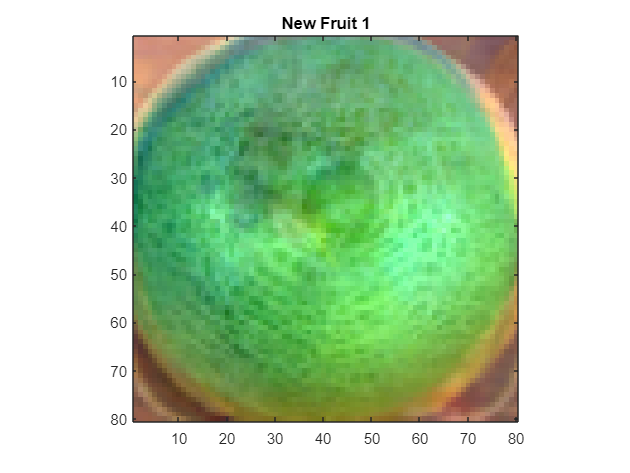

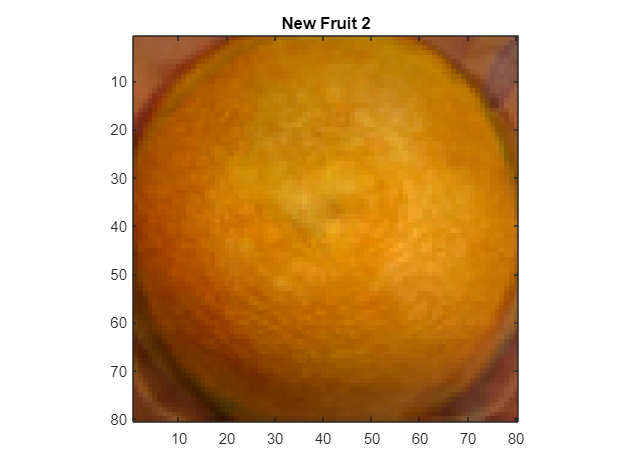

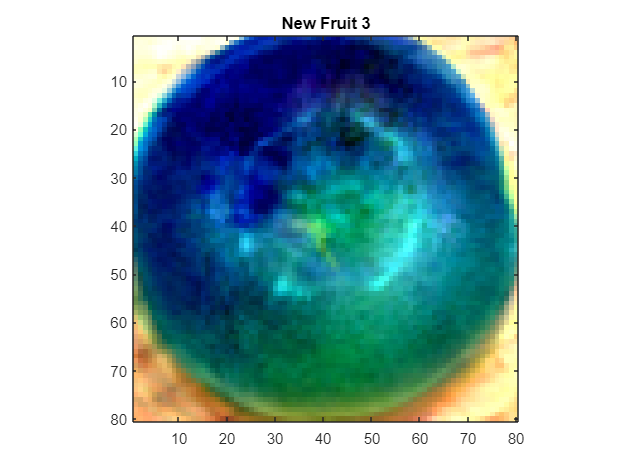


for i=(1:3)
    % mean + coordinate_transform*gaussian draw
    %nimg - newly generated fruit
    nimg = mu + Q*diag(sqrt(D))*randn(4,1);  %use the uniform distribution to select the 4 
                                            %components of the principal
                                            %eigenvectors
    figure,
    imagesc(reshape(nimg,80,80,3));   % new generated fruits
    title("New Fruit "+i);
    pbaspect([1,1,1]);
end